# Battery Cycle Life Prediction from Initial Operation Data

## **Part 1: Explore the Battery Dataset**

The original dataset contains measurements from 124 batteries. Training data contains (41 batteries), Validation data contains (43 batteries) and Test data (40 batteries). Data for each battery is stored in a structure, which includes the following information:

- Per-cycle summary data: Cycle number, discharge capacity, internal resistance, charge time

- Data collected within a cycle: Time, temperature, discharge capacity, voltage

load('batteryDischargeData.mat'); % load data of 5 Batteries
load('batteryDischargeDataPreprocessed.mat'); % load pre-computed values to be used for training and testing the model
helper.visualizeDataset(trainDataset);



*** Example Data of Battery 1 ***

    Cycle Number    Discharge Capacity    Internal Resistance    Charge Time
    ____________    __________________    ___________________    ___________

         1                     0                      0                 0   
         2                1.0939               0.016311            10.008   
         3                1.0951               0.016268            10.008   
         4                 1.096               0.016234            10.094   
         5                1.0965               0.016208            10.008   



## Part 2: Plot Discharge Capacity of Battery w.r.t Cycles

Plot discharge capacity for the first 1,000 cycles of a battery to visualize its change across the life of a battery. 

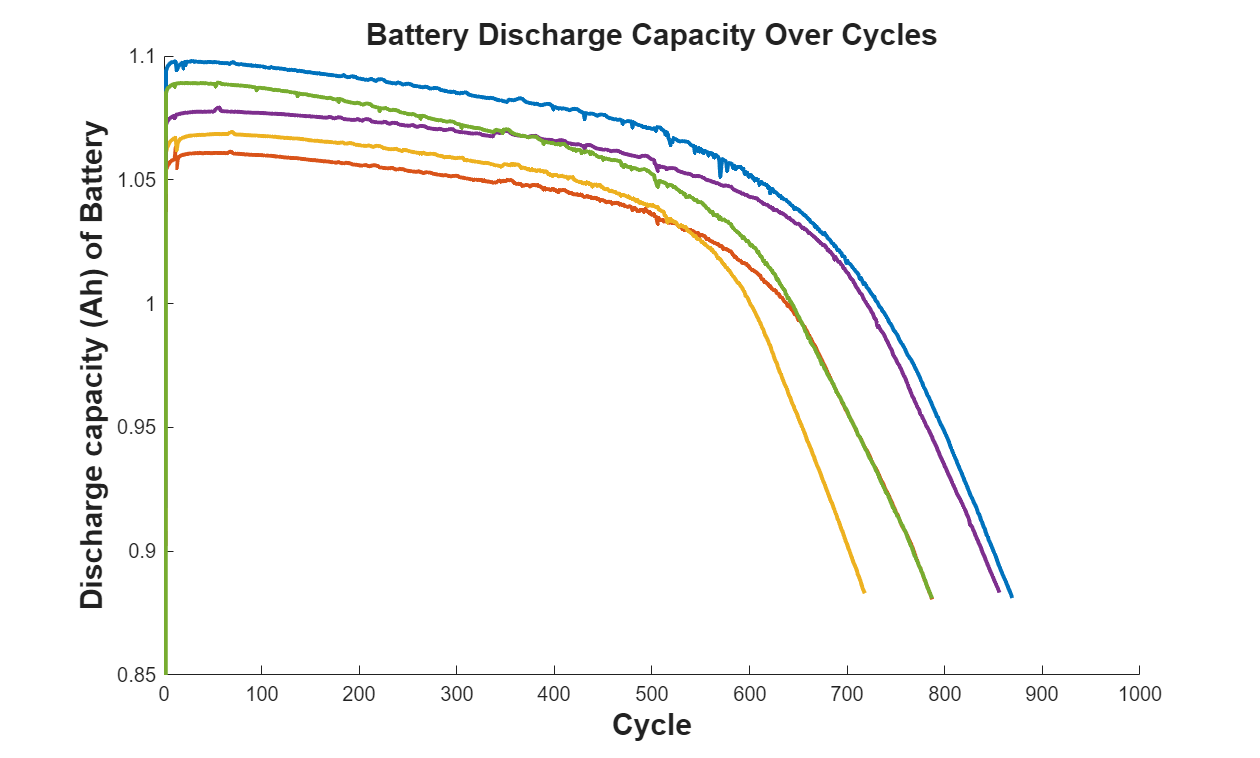

selectBatteries = 5; % Specify Number of Batteries to show
helper.visualizeDischargeCapacity(selectBatteries,trainDataset); %Plot of Discharge Capacity w.r.t Cycle

## Part 3: Model Development using **Linear Regression**

Extract the following features from the raw measurement data (the variable names are in brackets):

- Discharge Voltage($\Delta Q_{100-10}(V)$) log minimum [DeltaQ_min]

- Discharge capacity at cycle 2 [Qd2]

- Average charge time over first 5 cycles [AvgChargeTime]

- Minimum Internal Resistance, cycles 2 to 100 [MinIR]

- Internal Resistance difference between cycles 2 and 100 [IRDiff2And100]

helper.displayFeatures(XTrain); % Display the features extracted from raw dataset

    DeltaQ_min     Qd2      AvgChargeTime     MinIR      IRDiff2And100
    __________    ______    _____________    ________    _____________

     -1.9638      1.0753       13.409        0.016764     -3.3898e-05 
     -1.6928      1.0797       12.025        0.016098      4.4186e-05 
     -1.5889      1.0761       10.968        0.015923     -0.00012443 
     -1.4216      1.0939       10.025        0.016083     -3.7309e-05 
     -1.6089      1.0538       11.669        0.015963     -0.00030445 
     -1.5407      1.0611       10.798        0.016543     -0.00024655 
     -1.5077      1.0721       10.147        0.016238      2.2163e-05 
     -1.3383      1.0851       9.9247        0.016205     -6.6087e-05 



Use machine learning with linear regression to predict the remaining cycle life of a battery. Linear models have low computational cost but provide high interpretability.

[wModel, beta] = helper.trainClassifier(XTrain, yTrain); % Train multiple models and return the models with the lowest RMSE values
[wModelFinal, betaFinal] = helper.selectBestModel(XVal, yVal, wModel, beta); % Make model robust using Validation data with least RMSE

## Part 4(a): Run Inference on a (new) test battery

The test data contains measurements corresponding to 40 cells.

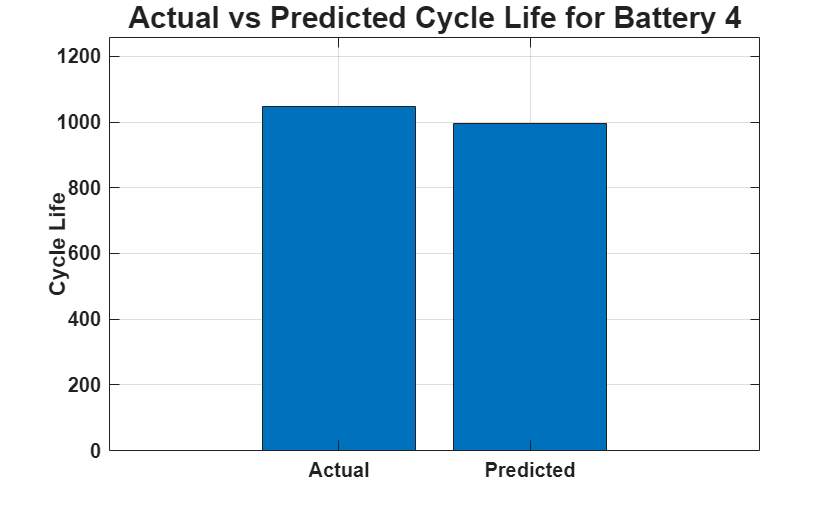

batteryIndex = "4"; %Select battery 1-4 to view Predicted Vs Actual battery life

batteryIndex = double(batteryIndex);

yBattery = yTest(batteryIndex); % yBattery corresponds to actual lifecycle of battery as present in testData

XBattery = XTest{batteryIndex, :}; % XBattery corresponds to battery data as present in testData

yPred = (XBattery * wModelFinal + betaFinal); % Calculate predicted lifecycle(yPred) of battery using trained model

helper.plotLifeCycleComparison(yBattery, yPred, batteryIndex); % Plot bar graph of Actual vs Predicted battery life

## Part 4(b): **Performance evaluation of the trained model**

The test data contains measurements corresponding to 40 batteries. Use the trained model to predict the remaining cycle life of each cell in `testData`.

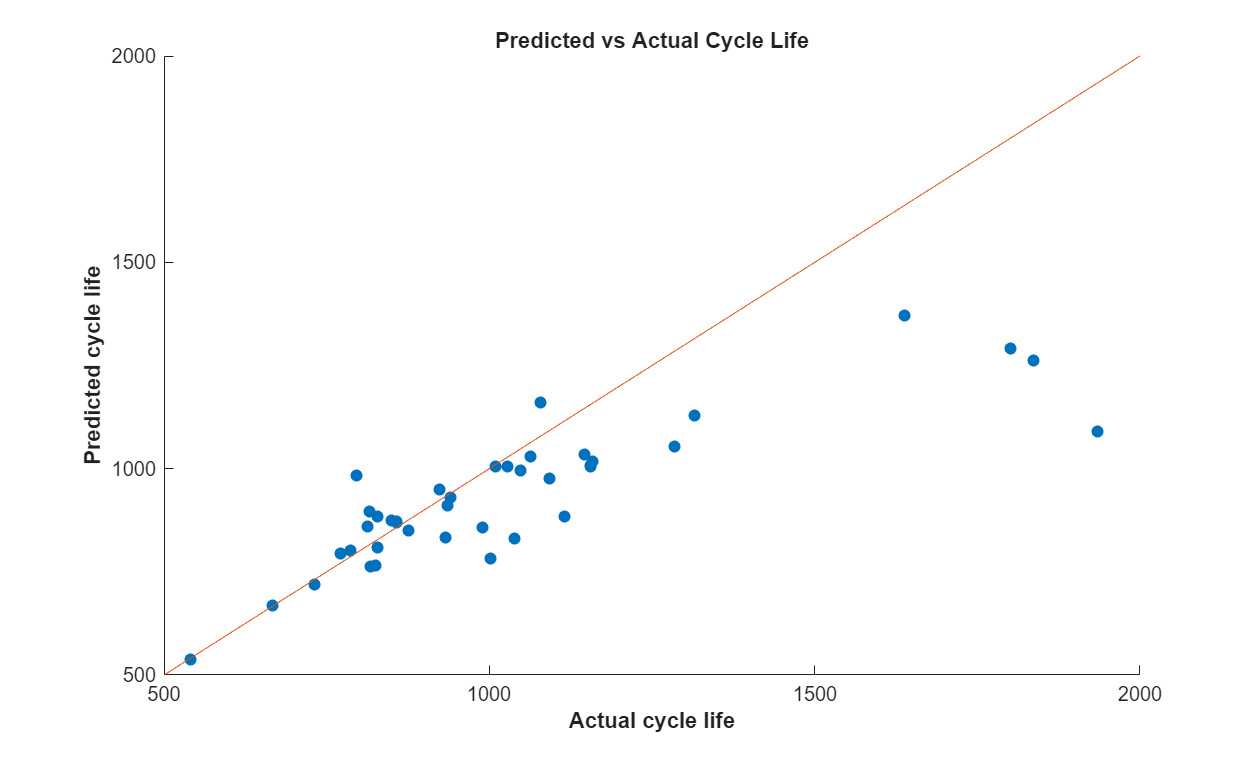

% XTest.Variables: Matrix of feature variables from the test data
% wModelFinal: Final weights of the trained model
% betaFinal: Intercept term of the trained model

yPredTest = (XTest.Variables*wModelFinal + betaFinal); % Compute predicted battery life using trained model

% Visualize the predicted vs. actual cycle life plot for the test data
helper.plotPerformanceEvaluation(yTest,yPredTest);

Ideally, all the points in the above plot should be close to the diagonal line. From the above plot, it is seen that the trained model is performing well when the remaining cycle life is between 500 and 1200 cycles. Beyond 1200 cycles, the model performance deteriorates. The model consistently underestimates the remaining cycle life in this region. This is primarily because test and validation data sets contain significantly more cells with total life around 1000 cycles. 

## Conclusion

This example showed how to use a linear regression model for battery cycle life prediction based on measurements from only the first 100 cycles. Custom features were extracted from the raw measurement data and a linear regression model was trained using training data. This model was used on test data for performance evaluation.

## **References**

[1] Severson, K.A., Attia, P.M., Jin, N. *et al.* "Data-driven prediction of battery cycle life before capacity degradation." *Nat Energy* **4, **383–391 (2019). https://doi.org/10.1038/s41560-019-0356-8

[2] [https://data.matr.io/1/](https://data.matr.io/1/) 

*Copyright 2024 The MathWorks, Inc.*